%%%Nominal values
%%%Biot Savart law at x=0
mu_0 = 4*pi*1e-7;    % Permeability in the vacum

IS501NMTB.X.L = 1.03;
IS501NMTB.X.R = 14.84;
IS501NMTB.X.a = IS501NMTB.X.L/2 ;
IS501NMTB.X.h = 0.5;
IS501NMTB.X.N = 36;
IS501NMTB.X.Lx = IS501NMTB.X.N^2*(2^(1/2)*mu_0*IS501NMTB.X.L^2)/(IS501NMTB.X.a*pi);
IS501NMTB.X.tau = IS501NMTB.X.Lx/IS501NMTB.X.R;

coeff_teor = @(N,a,h) (4 * mu_0 * N * a^2) / (pi) * (1/((a^2 + (h/2)^2) * (2 * a^2 + (h/2)^2)^(1/2)));

initial_1.x.Lx  = IS501NMTB.X.Lx;           %%0.00208911
initial_1.x.Rx  = IS501NMTB.X.R;            %%14.913
initial_1.x.B_1 = coeff_teor(IS501NMTB.X.N,IS501NMTB.X.a,IS501NMTB.X.h); %%5.38582e-05

initial = cell2mat(struct2cell(initial_1.x));

%%%1. Read data measured from the experiment
dt = 0.1;      %%Set sample time

%%% Read data measured from previous tests
fileName_x = 'data_20240114/xCoil_Epoch_2024_01_14.mat'; 
fileName_y = 'data_20240114/yCoil_Epoch_2024_01_14.mat'; 
fileName_z = 'data_20240114/zCoil_Epoch_2024_01_14.mat';
load(fileName_x); load(fileName_y); load(fileName_z);

%%% Interpretate and Clean Data
measuredData.xcoil = readProcessData(x_coil_data);
measuredData.ycoil = readProcessData(y_coil_data);
measuredData.zcoil = readProcessData(z_coil_data);
%%%Clear unused data
clear x_coil_data y_coil_data z_coil_data fileName_x fileName_y fileName_z
%%%Interpolate data to set the desired sampple time
[newDatos.x.t,newDatos.x.Bx] = setSampleTime(measuredData.xcoil.time, measuredData.xcoil.Bx,dt);
[~,newDatos.x.Ix] = setSampleTime(measuredData.xcoil.time, measuredData.xcoil.I,dt);
[~,newDatos.x.Vx] = setSampleTime(measuredData.xcoil.time,measuredData.xcoil.V,dt);

% 2. Represent the estimation data as an |iddata| object. 
y = [(measuredData.xcoil.Bx-30858.71)*1E-9;measuredData.xcoil.I]';
u = measuredData.xcoil.V';

z = iddata(y, u, dt, 'Name', 'Magnetic-testbed');

% 3. Specify input and output signal names, start time and time units. 
z.InputName = 'Voltage';
z.InputUnit =  'V';
z.OutputName = {'Magnetic Field', 'Current'};
z.OutputUnit = {'T', 'A'};
z.Tstart = 0;
z.TimeUnit = 's';

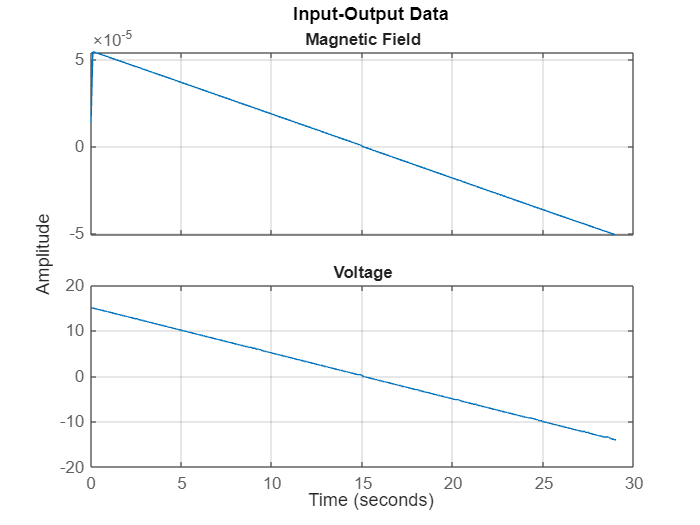

% 4. Plot the data.
%
% The data is shown in two plot windows.
figure('Name', [z.Name ': Voltage input -> Magnetic Field output']);
plot(z(:, 1, 1)); grid on;  % Plot first input-output pair (Voltage -> Angular position).

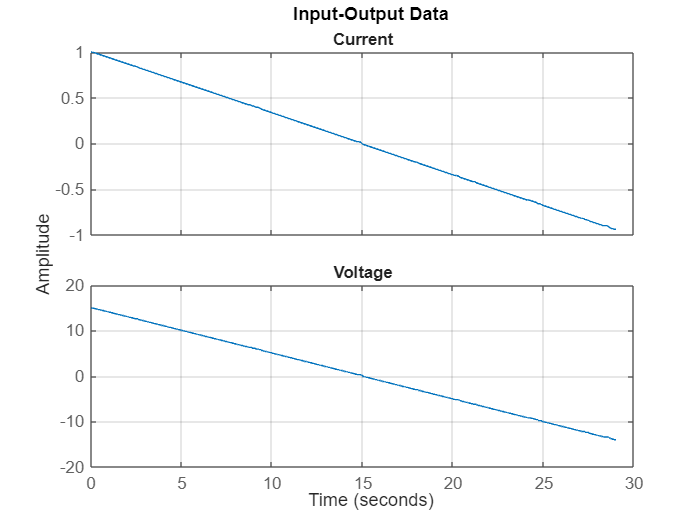

figure('Name', [z.Name ': Voltage input -> Current output']);
plot(z(:, 2, 1));  grid on; % Plot second input-output pair (Voltage -> Angular velocity).

% 2. Represent the DC motor dynamics using an |idnlgrey| object.
%
% The model describes how the inputs generate the outputs using the state
% equation(s).
FileName      = 'is501nmtbXaxis';       % File describing the model structure.
Order         = [2 1 1];           % Model orders [ny nu nx].
%Parameters    = [1; 0.28];        % Initial parameters. Np = 2.
Parameters    = initial';          % Initial parameters. Np = 3.
InitialStates = 0;            % Initial initial states.
%InitialStates = [0; 0];            % Initial initial states.
Ts            = 0;                 % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts, ...
                'Name', 'Magnetic-testbed');

% 3. Specify input and output names, and units.
set(nlgr, 'InputName', 'Voltage', 'InputUnit', 'V',               ...
          'OutputName', {'Magnetic Field', 'Current'}, ...
          'OutputUnit', {'T', 'A'},                         ...
          'TimeUnit', 's');

%4. Specify names and units of the initial states and parameters.
nlgr = setinit(nlgr, 'Name',  {'Current'});
nlgr = setinit(nlgr, 'Unit',  {'A'});
nlgr = setpar(nlgr, 'Name', {'L','R','P_1'});
nlgr = setpar(nlgr, 'Unit', {'H','ohm','T/A'});

%% 
%
% You can also use |setinit| and |setpar| to assign values, minima, maxima,
% and estimation status for all initial states or parameters
% simultaneously.
%
% 5. View the initial model.
%
% a. Get basic information about the model.
%
% The DC-motor has 2 (initial) states and 2 model parameters.
size(nlgr)

Nonlinear grey-box model with 2 outputs, 1 inputs, 1 states and 3 parameters (3 free).


%
%
% b. View the initial states and parameters.
%
% Both the initial states and parameters are structure arrays. The fields
% specify the properties of an individual initial state or parameter. Type
% |help idnlgrey.InitialStates| and |help idnlgrey.Parameters| for
% more information.
nlgr.Parameters(1).Minimum = 0;
nlgr.Parameters(1)

ans = struct with fields:
       Name: 'L'
       Unit: 'H'
      Value: 0.0015
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(2).Minimum = 0;
nlgr.Parameters(2).Fixed = 0;
nlgr.Parameters(2)

ans = struct with fields:
       Name: 'R'
       Unit: 'ohm'
      Value: 14.8400
    Minimum: 0
    Maximum: Inf
      Fixed: 0


nlgr.Parameters(3).Minimum = 0;
nlgr.Parameters(3).Fixed = 0;
nlgr.Parameters(3)

ans = struct with fields:
       Name: 'P_1'
       Unit: 'T/A'
      Value: 6.0537e-05
    Minimum: 0
    Maximum: Inf
      Fixed: 0


%%
%
% c. Retrieve information for all initial states or model parameters in one
% call.
% 
% For example, obtain information on initial states that are fixed (not
% estimated) and the minima of all model parameters.
getinit(nlgr, 'Fixed')

ans = 1×1 cell array
    {[1]}


getpar(nlgr, 'Min')

ans = 3×1 cell array
    {[0]}
    {[0]}
    {[0]}


%
% d. Obtain basic information about the object:
nlgr

nlgr =

Continuous-time nonlinear grey-box model defined by 'is501nmtbXaxis' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p3)
    y(t) = H(t, u(t), x(t), p1, ..., p3) + e(t)

 with 1 input(s), 1 state(s), 2 output(s), and 3 free parameter(s) (out of 3).

Name: Magnetic-testbed

Status:                                                         
Created by direct construction or transformation. Not estimated.

Model Properties


%%
% Use |get| to obtain more information about the model properties. The
% |idnlgrey| object shares many properties of parametric linear model
% objects.
get(nlgr)

             FileName: 'is501nmtbXaxis'
                Order: [1×1 struct]
           Parameters: [3×1 struct]
        InitialStates: [1×1 struct]
         FileArgument: {}
    SimulationOptions: [1×1 struct]
         TimeVariable: 't'
        NoiseVariance: [2×2 double]
            InputName: {'Voltage'}
            InputUnit: {'V'}
           InputGroup: [1×1 struct]
           OutputName: {2×1 cell}
           OutputUnit: {2×1 cell}
          OutputGroup: [1×1 struct]
                Notes: [0×1 string]
             UserData: []
                 Name: 'Magnetic-testbed'
                   Ts: 0
             TimeUnit: 'seconds'
               Report: [1×1 idresults.nlgreyest]



%% Performance Evaluation of the Initial DC-Motor Model
%
% Before estimating the parameters |tau| and |k|, simulate the output of
% the system with the parameter guesses using the default differential
% equation solver (a Runge-Kutta 45 solver with adaptive step length
% adjustment). The simulation options are specified using the
% "SimulationOptions" model property.
%
% 1. Set the absolute and relative error tolerances to
% small values (|1e-6| and |1e-5|, respectively).
nlgr.SimulationOptions.AbsTol = 1e-6;
nlgr.SimulationOptions.RelTol = 1e-5;


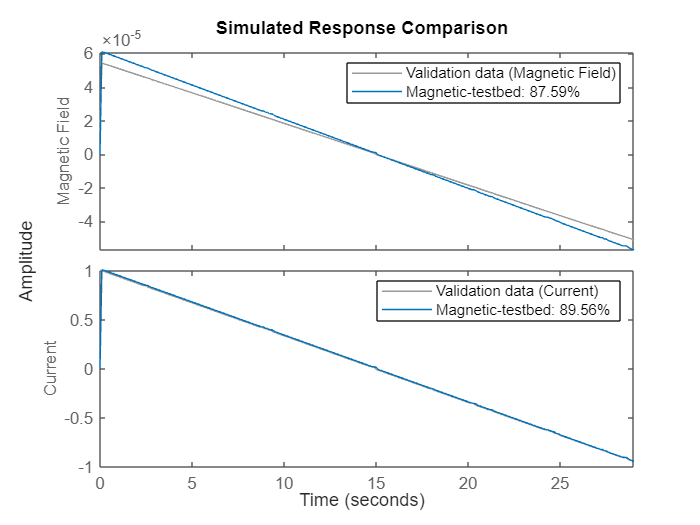

%%
%
% 2. Compare the simulated output with the measured data.
%
% |compare| displays both measured and simulated outputs of one or more
% models, whereas |predict|, called with the same input arguments, displays
% the simulated outputs.
%
% The simulated and measured outputs are shown in a plot window.
compare(z, nlgr);

%% Parameter Estimation
% Estimate the parameters and initial states using |nlgreyest|, which is a
% prediction error minimization method for nonlinear grey box models. The
% estimation options, such as the choice of estimation progress display,
% are specified using the "nlgreyestOptions" option set.
nlgr = setinit(nlgr, 'Fixed', {false}); % Estimate the initial states.
opt = nlgreyestOptions('Display', 'on');
nlgr = nlgreyest(z, nlgr, opt);


function coil = readProcessData(coil_data)
    %%%Interpretate data
    time = coil_data(1,:); Bx = coil_data(2,:); 
    By   = coil_data(3,:); Bz = coil_data(4,:);
    V    = coil_data(5,:); I  = coil_data(6,:);
    %%%Clean data
    coil.time = time(~isnan(time));
    coil.Bx = Bx(~isnan(Bx)); 
    coil.By = By(~isnan(By)); 
    coil.Bz = Bz(~isnan(Bz));
    coil.V  = V(~isnan(V)); 
    coil.I  = I(~isnan(I));
end

function [ t_uniform, x_uniform] = setSampleTime(tout,data,t_sample)
    %%% Interpolation to have uniform sampling
    %temp = diff(tout);               %%Temporal time
    %t_sample = mean(temp(1:end-1));                             %%Get sample time
    t_uniform = tout(1):t_sample:tout(end); %%Define a uniform time vector
    %%% Start interpolation
    x_uniform = interp1(tout, data, t_uniform, 'spline');  % Interpolación
end